soft_folder = "soft_gripper_expts_2/";
soft_files = ["expt_2.mat";"expt_3.mat";"expt_5.mat";"expt_6.mat";"expt_10.mat"];

rigid_folder = "rigid_gripper_expts_2/";
rigid_files = ["expt_1.mat";"expt_2.mat";"expt_8.mat";"expt_9.mat";"expt_10.mat"];

% plot variables here
titlefsz = 20;
textfsz = 17;
axfsz = 15;
linewidth = 2;

figure;
theme(figure,"light");

load(rigid_folder + rigid_files(3));
net_area = area(1,:) + area(2,:) + area(3,:) + area(4,:) + area(5,:) + area(6,:) + area(7,:) + area(8,:);
net_area = net_area';
plot(at,net_area,"Color",[0 0.5 0],"LineWidth",linewidth);
hold on;

t_start = ot(i1) - 0.4;
t_start = t_start*(ones(size(ot,1),1));

t_end = ot(i2) - 0.4;
t_end = t_end*(ones(size(ot,1),1));

y_axis = linspace(0,10e-4,size(ot,1));

plot(t_start,y_axis,"--","Color","red","LineWidth",linewidth + 0.3);
plot(t_end,y_axis,"--","Color","red","LineWidth",linewidth + 0.3);

ax = gca;
ax.FontSize = axfsz;
xlabel("Time (s)","FontSize",textfsz);
ylabel("Net Compression (m)","FontSize",textfsz);
title("Net Compression vs Time","FontSize",titlefsz);
xlim([0,25]);
ylim([0,10e-4]);
grid on;


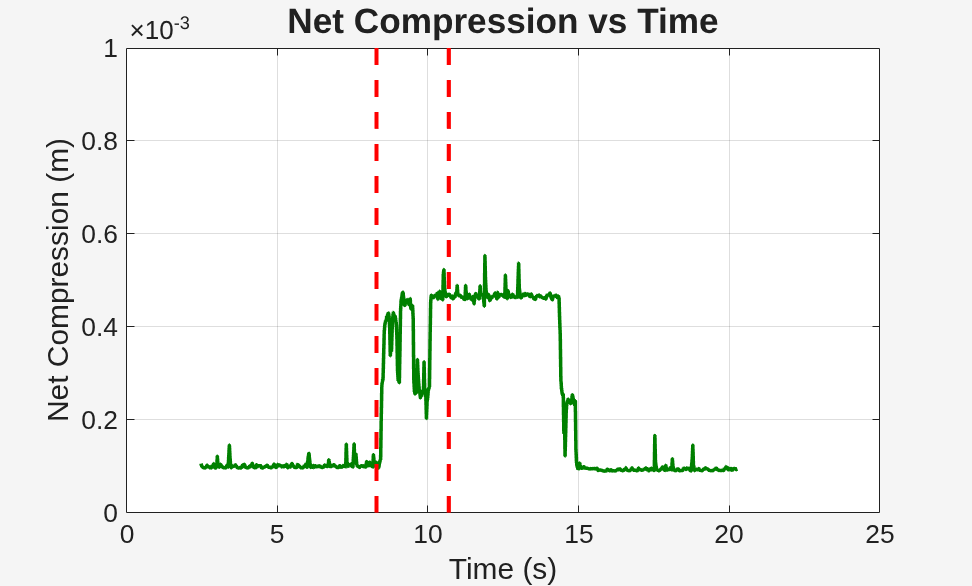


saveas(gcf,"Rigid grpper net area.png");
hold off;

load("characteristic_2.mat");
k = k/2;
r = r/2;
fz_left = -1*estimate_lattice_force(enc(:,1),ot,t_inv,k,r(1),r(2),kr);

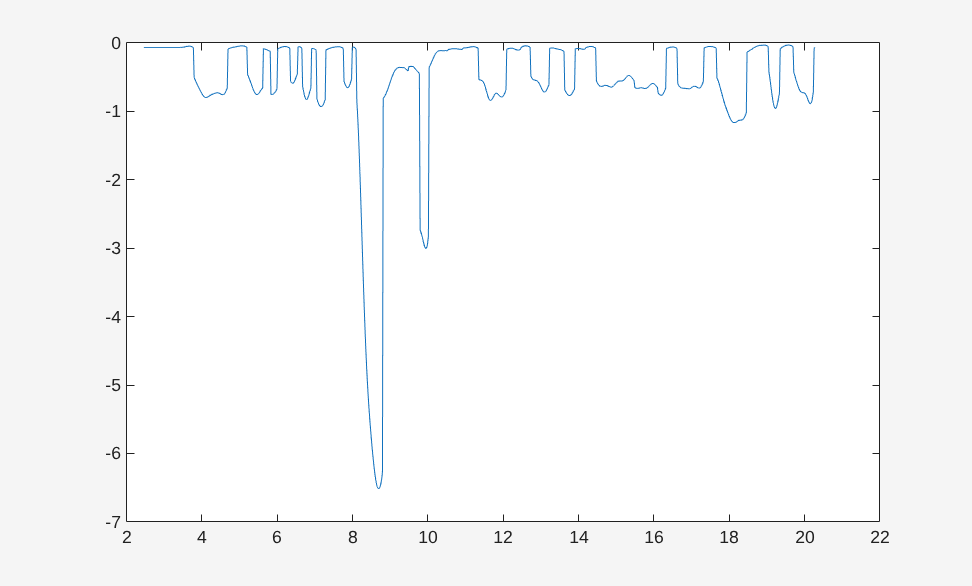

plot(ot,fz_left);